# Metodo dei minimi quadrati

#### Esercizio 1)

La tabella mostra i valori annuali di concentrazione di CO2 nell’atmosfera (in parti per milioni (ppm)) nella penisola Antartica. Determinare la retta che approssima tali dati nel senso dei minimi quadrati ed il valore della concentrazione di CO2 nell’anno 2010.

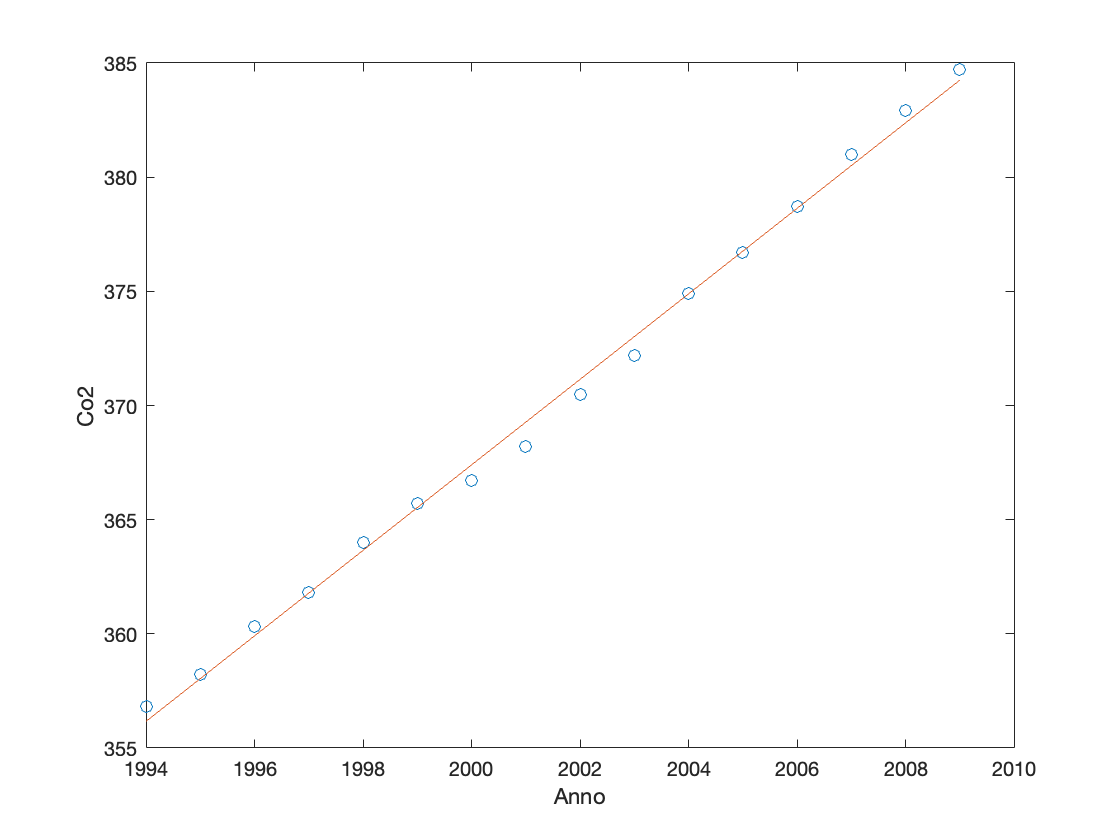

anno = 1994:2009; % 16 nodi
ppm = [356.8, 358.2, 360.3, 361.8, 364.0, 365.7, 366.7, 368.2, 370.5, 372.2, 374.9, 376.7, 378.7, 381.0, 382.9, 384.7];

plot(anno, ppm, 'o')
hold on

a = myls(anno, ppm, 2);
P_m = @(x) a(1) + a(2)*x;

plot(anno, P_m(anno))
xlabel('Anno');
ylabel('Co2');
hold off

fprintf('La concentrazione di CO2 nel 2010 è stata di %3.1f ppm', P_m(2010))

La concentrazione di CO2 nel 2010 è stata di 386.1 ppm

#### Esercizio 2)

La tabella mostra i valori della densità relativa dell’aria $\rho$ misurata a varie altitudini $h$. Usare l’approssimazione quadratica dei minimi quadrati per determinare la densità relativa dell’aria per $h = 10.5 km$. 

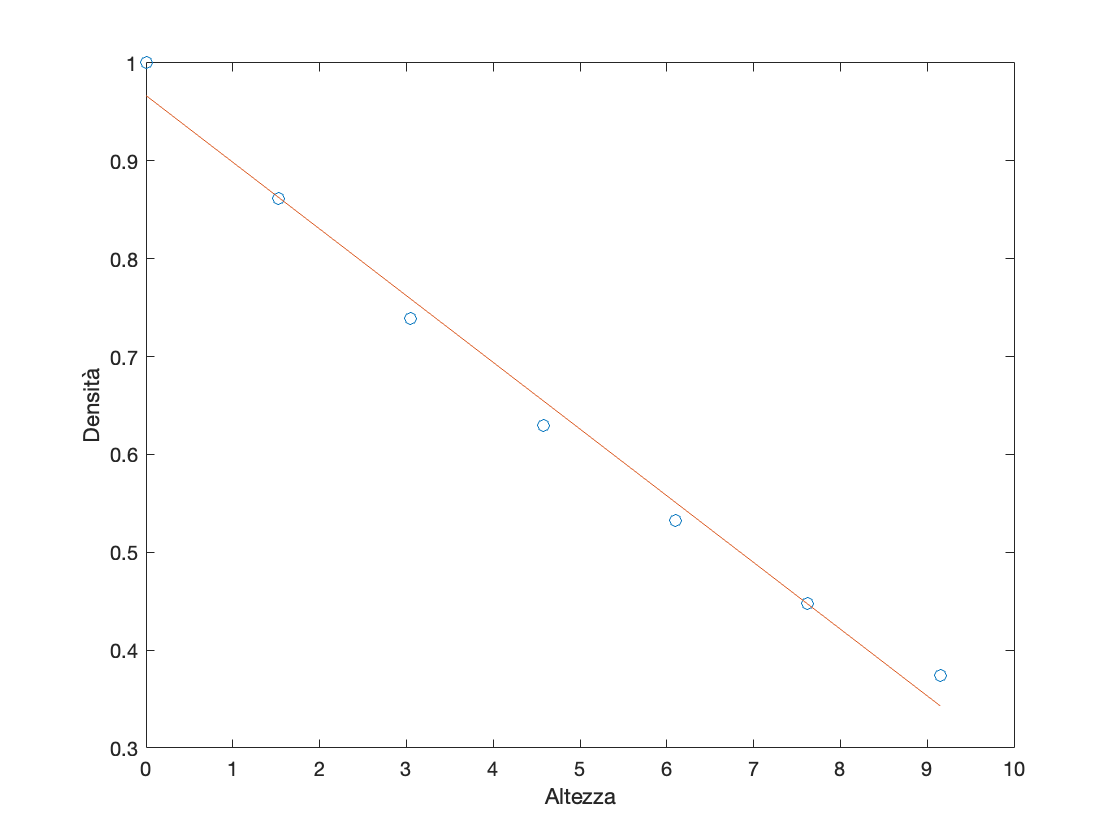

h = [0, 1.525, 3.050, 4.575, 6.10, 7.625, 9.150];
p = [1, 0.8617, 0.7385, 0.6292, 0.5328, 0.4481, 0.3741];

plot(h, p, 'o')
hold on

a = myls(h, p, 2);
P_m= @(x) a(1) + a(2)*x;

plot(h, P_m(h));
xlabel('Altezza');
ylabel('Densità');
hold off

fprintf('La densità dell aria ad un altezza di 10.5 km è %1.4f', P_m(10.5))

La densità dell aria ad un altezza di 10.5 km è 0.2510

#### Esercizio 3)

La viscosità cinematica dell’aria $\mu_k$ varia con la temperatura $T$ come mostrato in tabella. Determinare il polinomio cubico che meglio approssima i dati nel senso dei minimi quadrati ed usarlo per calcolare $\mu_k$ per $T = 10°, 30°, 60° e 90°$.

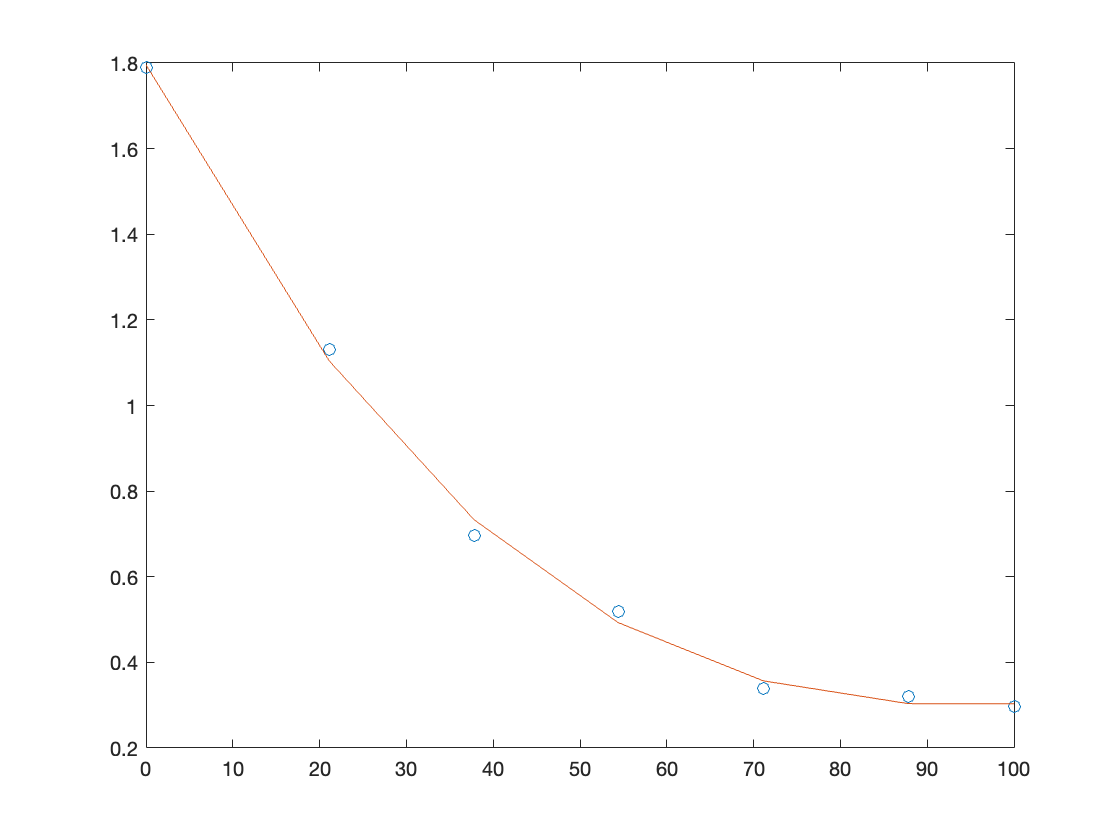

T = [0, 21.1, 37.8, 54.4, 71.1, 87.8, 100];
mu_k = [1.79, 1.13, 0.696, 0.519, 0.338, 0.321, 0.296];

plot(T, mu_k, 'o')
hold on

a = myls(T, mu_k, 4);
P_m = @(x) a(1) + a(2)*x + a(3)*x.^2 + a(4)*x.^3;

plot(T, P_m(T))
hold off

fprintf('La viscosità cinematica dell aria a 10° è %1.3f', P_m(10));

La viscosità cinematica dell aria a 10° è 1.435

fprintf('La viscosità cinematica dell aria a 30° è %1.3f', P_m(30));

La viscosità cinematica dell aria a 30° è 0.889

fprintf('La viscosità cinematica dell aria a 60° è %1.3f', P_m(60));

La viscosità cinematica dell aria a 60° è 0.437

fprintf('La viscosità cinematica dell aria a 90° è %1.3f', P_m(90));

La viscosità cinematica dell aria a 90° è 0.302

#### Esercizio 4)

I dati seguenti rappresentano la crescita di batteri in un liquido di coltura in un certo numero di giorni. 

- Determinare la funzione che meglio approssima i dati nel senso dei minimi quadrati. Provare diverse possibilità: lineare, quadratica ed esponenziale. 

- Determinare la migliore equazione per la predizione del numero di batteri dopo 35 giorni.

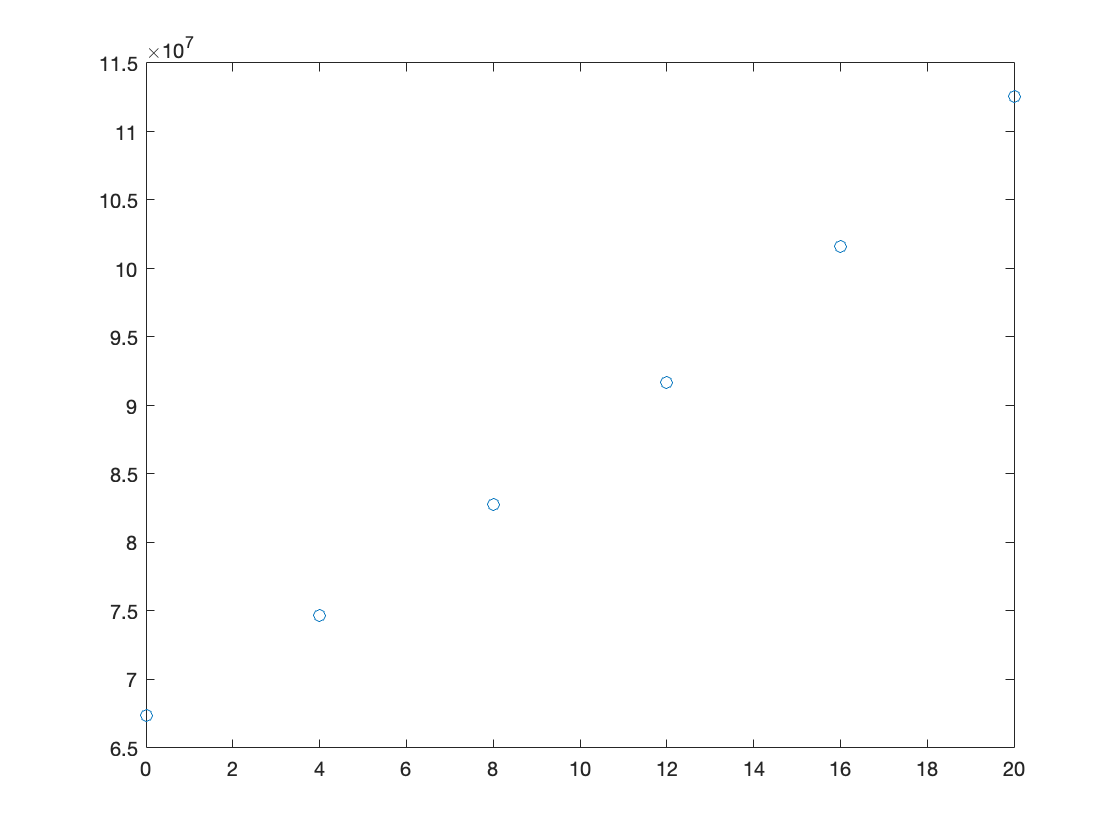

giorni = [0, 4, 8, 12, 16, 20];
batteri = [67.38, 74.67, 82.74, 91.69, 101.60, 112.58];
batteri = batteri .* 10^6;
n = length(giorni);

plot(giorni, batteri, 'o')

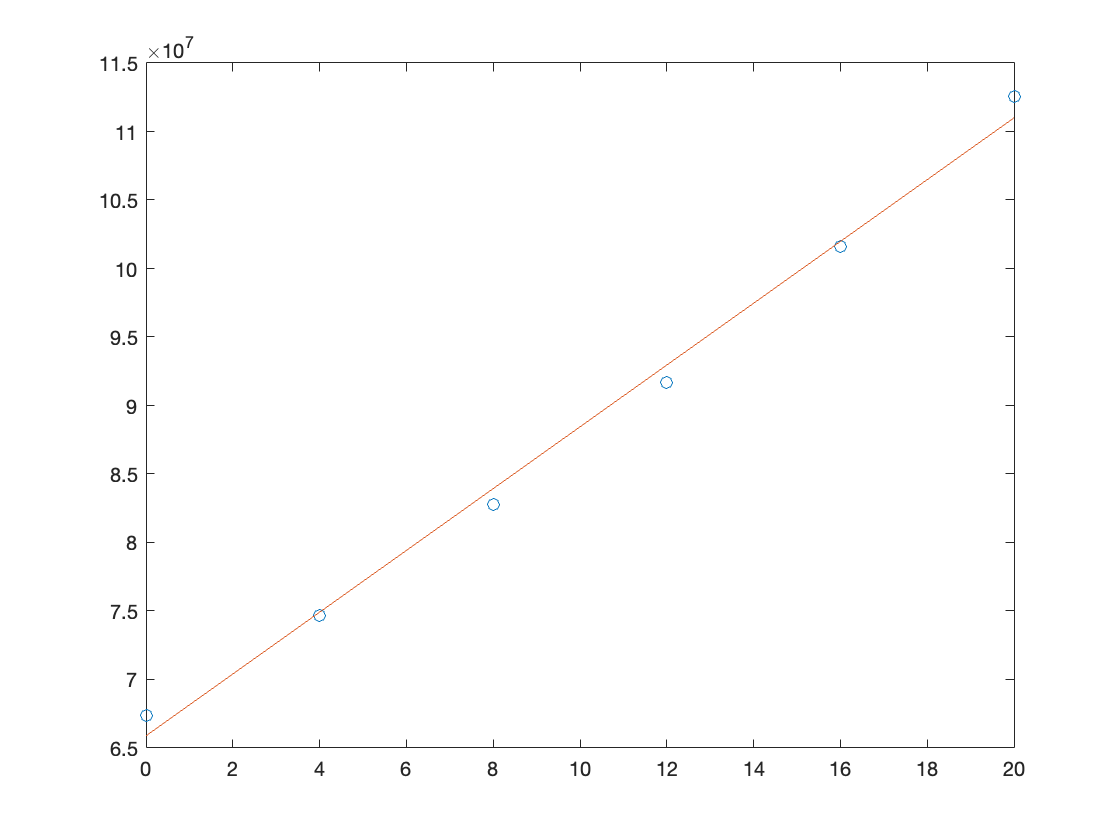

% Proviamo con una retta, e calcoliamo lo scarto quadratico
a2 = myls(giorni, batteri, 2);
P_2 = @(x) a2(1) + a2(2)*x;

plot(giorni, batteri, 'o', giorni, P_2(giorni))
hold on
sq_2 = sum((batteri - P_2(giorni)).^2);
er_2 = sqrt(sq_2 / n);
hold off

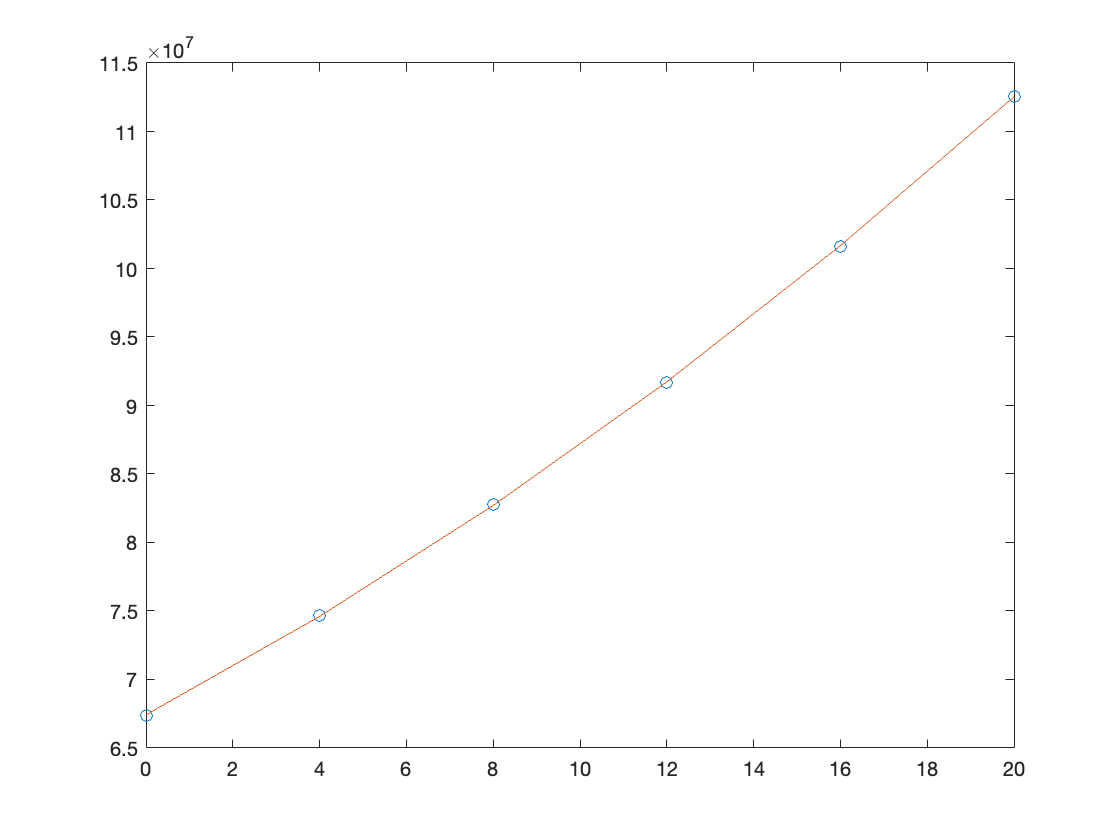

% Proviamo con una parabola
a3 = myls(giorni, batteri, 3);
P_3 = @(x) a3(1) + a3(2)*x + a3(3)*x.^2;

plot(giorni, batteri, 'o', giorni, P_3(giorni))
hold on

sq_3 = sum((batteri - P_3(giorni)).^2);
er_3 = sqrt(sq_3 / n);
hold off

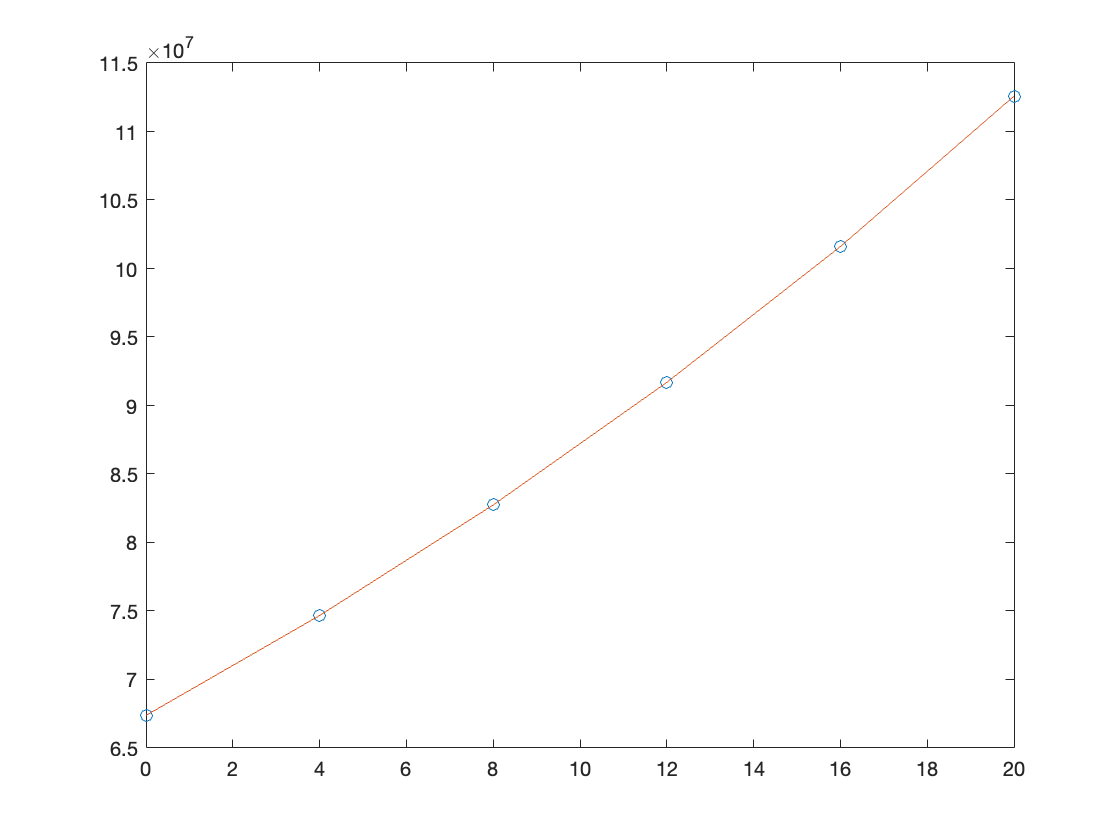

% Proviamo con un polinomio cubico
a_4 = myls(giorni, batteri, 4);
P_4 = @(x) a_4(1) + a_4(2)*x + a_4(3)*x.^2 + a_4(4)*x.^3;

plot(giorni, batteri, 'o', giorni, P_4(giorni))
hold on
sq_4 = sum((batteri - P_4(giorni)).^2);
er_4 = sqrt(sq_4/n);
hold off

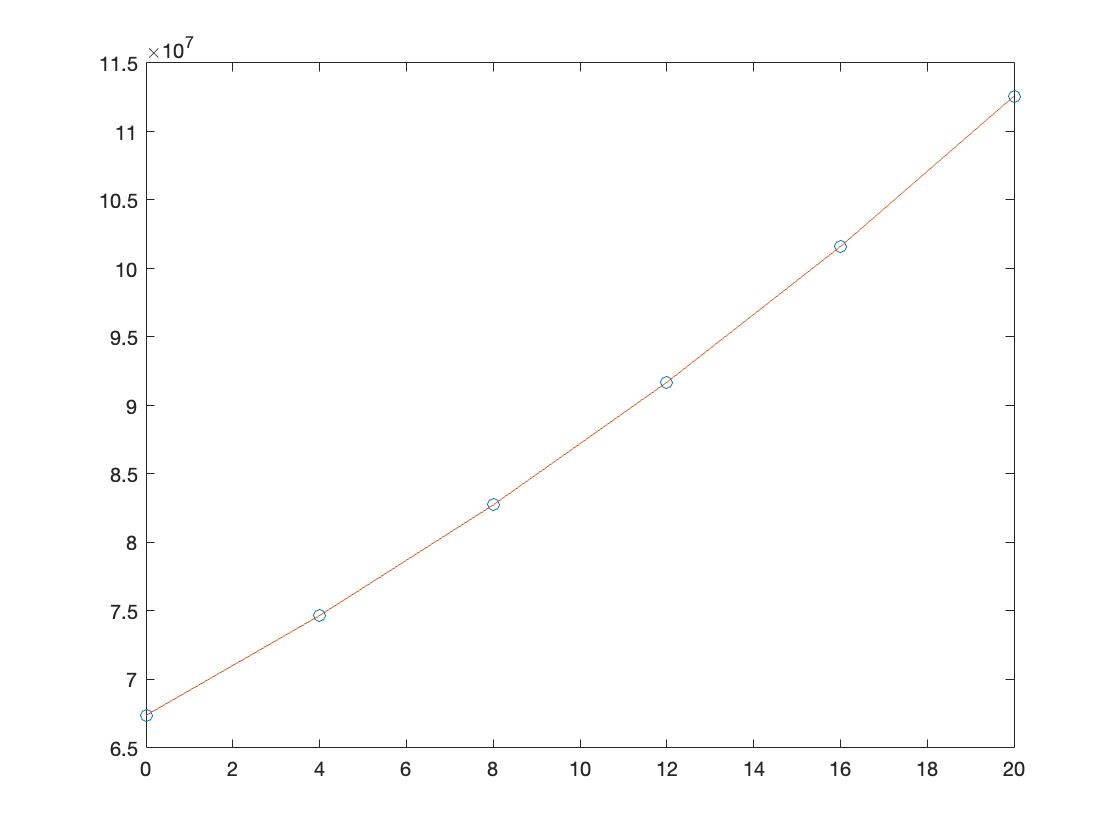

% Proviamo con un polinomio di grado 4
a_5 = myls(giorni, batteri, 5);
P_5 = @(x) a_5(1) + a_5(2)*x + a_5(3)*x.^2 + a_5(4)*x.^3 + a_5(5)*x.^4;

plot(giorni, batteri, 'o', giorni, P_5(giorni))
hold on
sq_5 = sum((batteri - P_5(giorni)).^2);
er_5 = sqrt(sq_5/n);
hold off

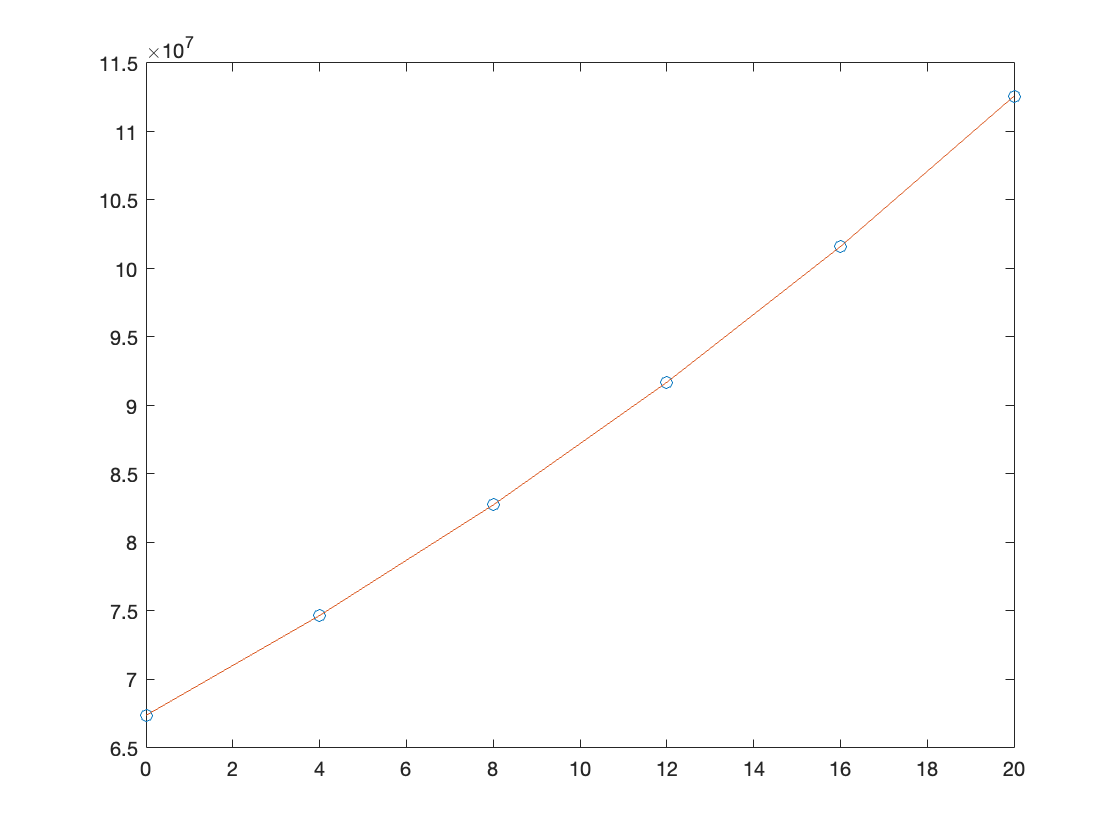

% Proviamo con un polinomio di grado 5 (tecnicamente dovrebbe uscire
% l'interpolazione)
a_6 = myls(giorni, batteri, 6);
P_6 = @(x) a_6(1) + a_6(2)*x + a_6(3)*x.^2 + a_6(4)*x.^3 + a_6(5)*x.^4 + a_6(6)*x.^5;

plot(giorni, batteri, 'o', giorni, P_6(giorni))
hold on
sq_6 = sum((batteri - P_6(giorni)).^2);
er_6 = sqrt(sq_6/n);
hold off

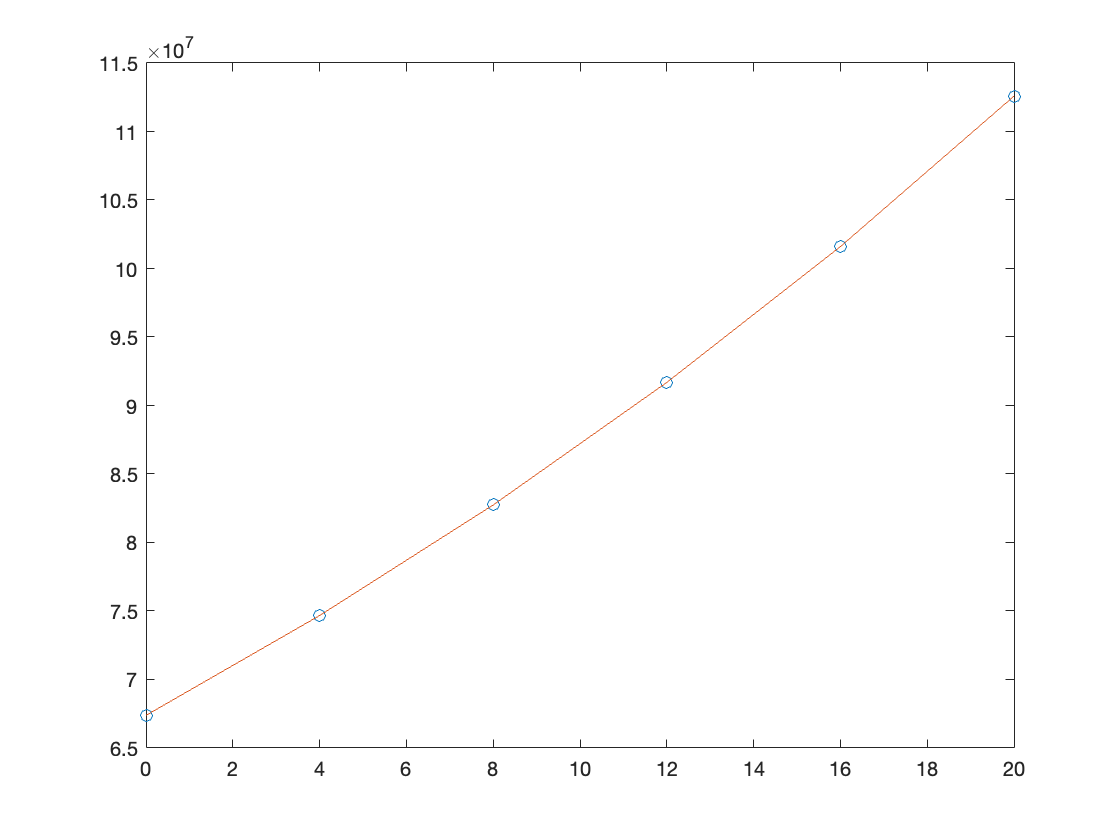

% Proviamo con l'esponenziale
X = giorni;
Y = log(batteri);
a_exp = myls(X, Y, 2);
P_exp = @(x) a_exp(1) + a_exp(2)*x;

plot(giorni, batteri, 'o', giorni, exp(P_exp(giorni)))
hold on
sq_exp = sum((batteri - exp(P_exp(giorni))).^2);
er_exp = sqrt(sq_exp/n);
hold off

% Verifichiamo i risulatati ottenuti
fprintf('L errore medio usando un polinomio lineare è %e', er_2);

L errore medio usando un polinomio lineare è 1.150819e+06

fprintf('L errore medio usando un polinomio quadratico è %e', er_3);

L errore medio usando un polinomio quadratico è 5.144692e+04

fprintf('L errore medio usando un polinomio cubico è %e', er_4);

L errore medio usando un polinomio cubico è 1.499559e+03

fprintf('L errore medio usando un polinomio quartico è %e', er_5);

L errore medio usando un polinomio quartico è 1.285861e+03

fprintf('L errore medio usando un polinomio quintico è %e', er_6);% Interpolazione ? 

L errore medio usando un polinomio quintico è 8.310454e-06

fprintf('L errore medio usando exp è %e', er_exp);

L errore medio usando exp è 2.603147e+03

#### Esercizio 5)

Si considerino i seguenti dati, che possono essere rappresentati dalla seguente equazione $x = e^{(y-b)/a}$, dove $a$ e $b$ sono parametri. Determinare $a$ e $b$ e disegnare il grafico della funzione. 						

clear
x = 1:5;
y = [0.5, 2, 2.9, 3.5, 4];

plot(y, x, 'o')
hold on

Applochiamo il logaritmo otteniamo:

- 
$$log(x) = log(e^{(y-b)/a})$$


- 
$$log(x) = \frac{y-b}{a}$$


- 
$$a \; log(x) = y - b$$


- 
$$y = b + a \; log(x)$$


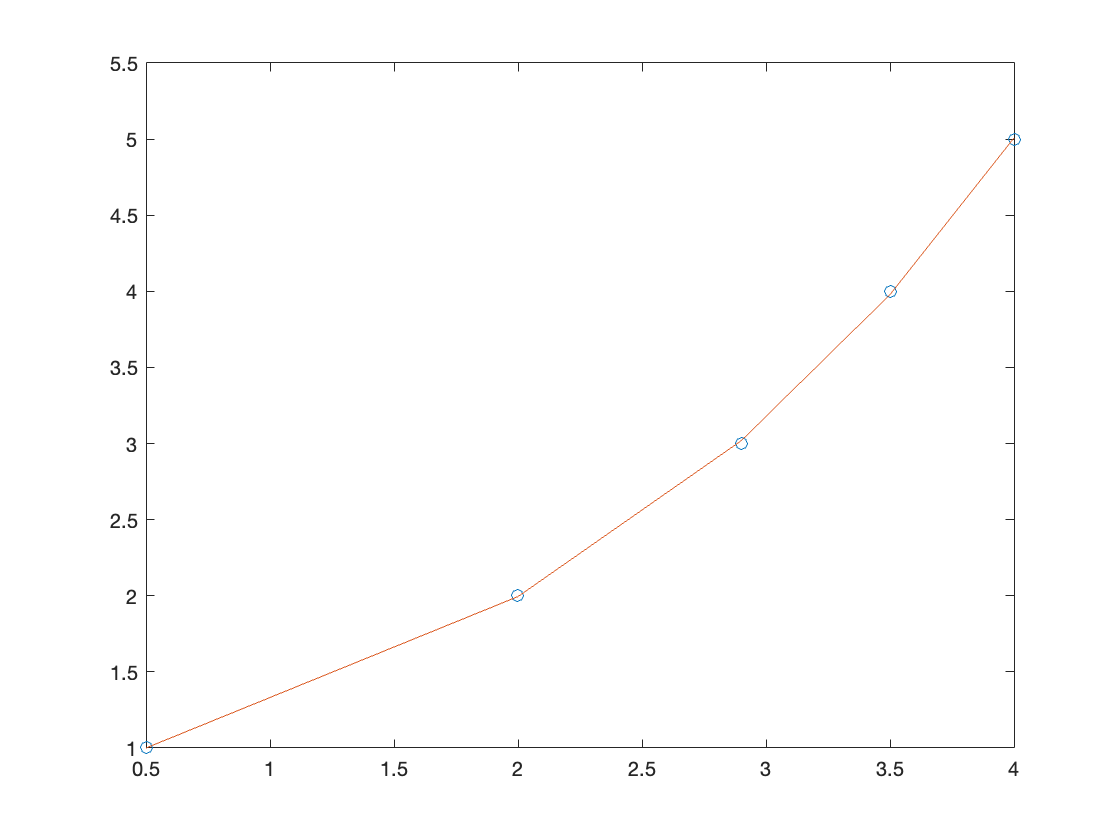

a = myls(log(x), y, 2);

f = @(y) exp((y - a(1))./a(2));

plot(y, f(y))
hold off

#### Esercizio 6)

Risolvere gli esercizi 9, 11 e 13 pag. 508-509 del libro Numerical Analysis di Burden-Faires. 

- The following table lists the college grade-point averages of 20 mathematics and computer science majors, together with the scores that these stuents received on the mathematics portion of the ACT test while in high school. **Plot these data, and find the equation of the least square line for this data**.

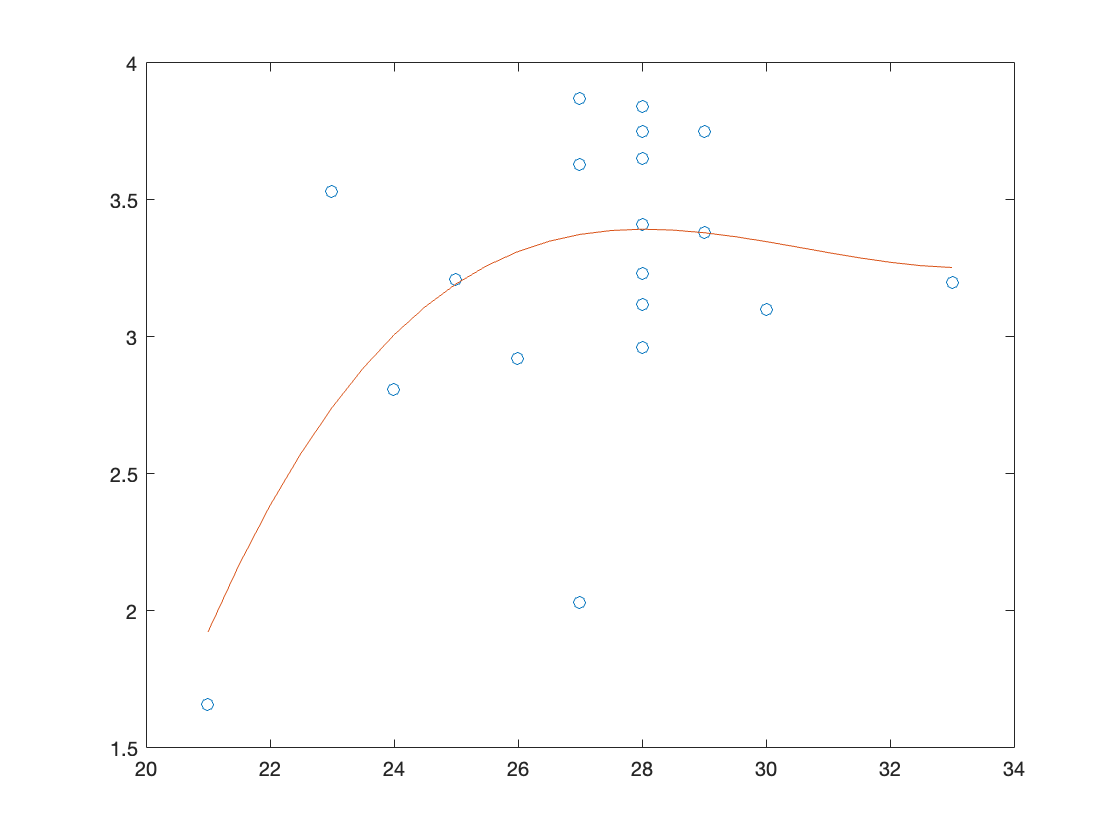

clear
ACT_score = [28, 29, 25, 28, 28, 27, 27, 29, 28, 21, 33, 28, 28, 28, 29, 26, 23, 30, 27, 24];
Grade_Point = [3.84, 3.75, 3.21, 3.65, 3.23, 3.87, 3.63, 3.75, 3.75, 1.66, 3.20, 3.12, 3.41, 2.96, 3.38, 2.92, 3.53, 3.10, 2.03, 2.81];

plot(ACT_score, Grade_Point, 'o')
hold on

a = myls(ACT_score, Grade_Point, 4); % Usando un polinomio di grado maggiore di 2 non esce una funzione PROBLEMA DI CONTINUITà DEL DOMINIO
P_m = @(x) a(1) + a(2)*x + a(3)*x.^2 + a(4)*x.^3;

myScore = min(ACT_score): 0.5 :max(ACT_score); % Provo a rendere il dominio più continuo

plot(myScore, P_m(myScore))

sq = sum((Grade_Point - P_m(Grade_Point)).^2); 
er = sqrt(sq/length(Grade_Point));
hold off

fprintf('L errore medio è di %e', er);

L errore medio è di 4.006434e+01

- Sto calcolando l'errore sulla giusta funzione? E' solo un problema di matlab? Come rimedio?

- To determine a relationship between the number of fish and the number of species of fish in samples taken for a portion of the Great Barrier Reef, P. Sale and R. Dybdahl [SD] fit a linear least squares polynomial to the following collection of data, which were collected in samples over a 2-year period. Let *x *be the number of fish in the sample and *y *be the number of species in the sample. **Determine the linear least squares polynomial for these data.**

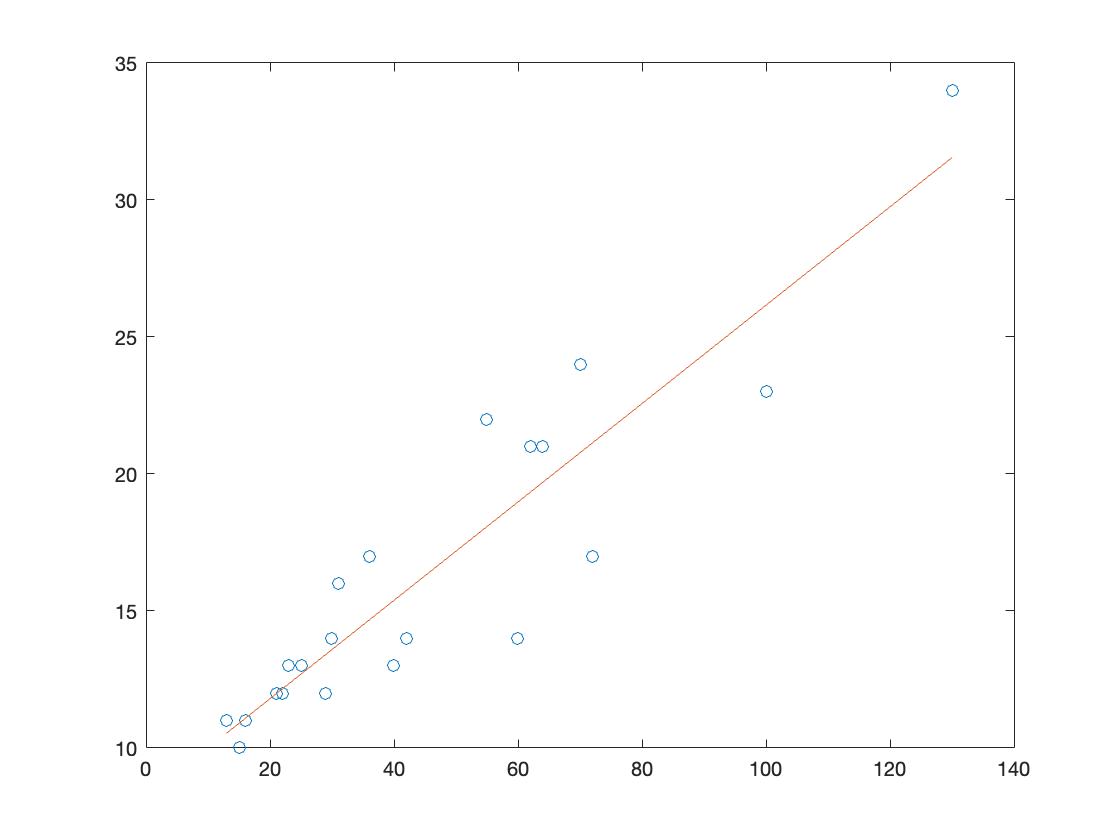

x = [13, 15, 16, 21, 22, 23, 25, 29, 30, 31, 36, 40, 42, 55, 60, 62, 64, 70, 72, 100, 130]; % Number of fish
y = [11, 10, 11, 12, 12, 13, 13, 12, 14, 16, 17, 13, 14, 22, 14, 21, 21, 24, 17, 23, 34]; % Species

plot(x, y, 'o')
hold on
a = myls(x, y, 2);
P_2 = @(x) a(1) + a(2)*x;

plot(x, P_2(x))
hold off

- In a paper dealing with the efficiency of energy utilization of the larvae of the modest sphinx moth (*Pachysphinx modesta*), L. Schroeder [Schr1] used the following data to determine a relation between $W$, the live weight of the larvae in grams, and $R$, the oxygen consumption of the larvae in milliliters/hour. For biological reasons, it is assumed that a relationship in the form of $R = bW^a$ exists between $W$ and $R$. 

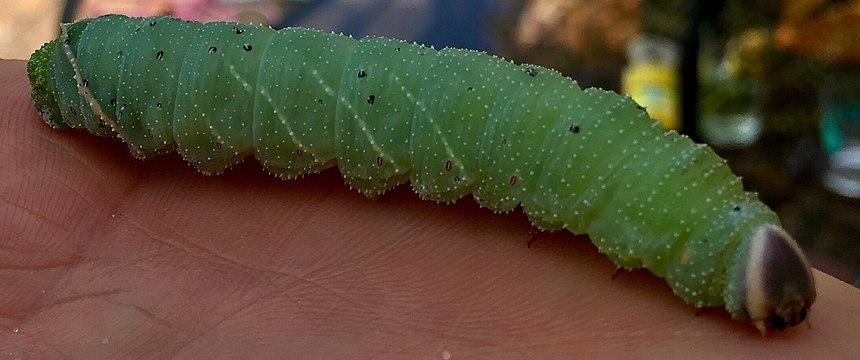

- **Find the logarithmic linear least squares polynomial by using **$log(R) = log(b) + a \; log(W)$

- **Compute the error associated with the approximation in part (a):  **$E = \sum_{i=1}^{37}(R_i - bW_i^a)^2$

- **Modify the logarithmic least squares equation in part (a) by adding the quadratic term** $c(log(W_i))^2$** , and determine the logarithmic quadratic least squares polynomial. **

- **Determine the formula for and compute the error associated with the approximation in part (c). **

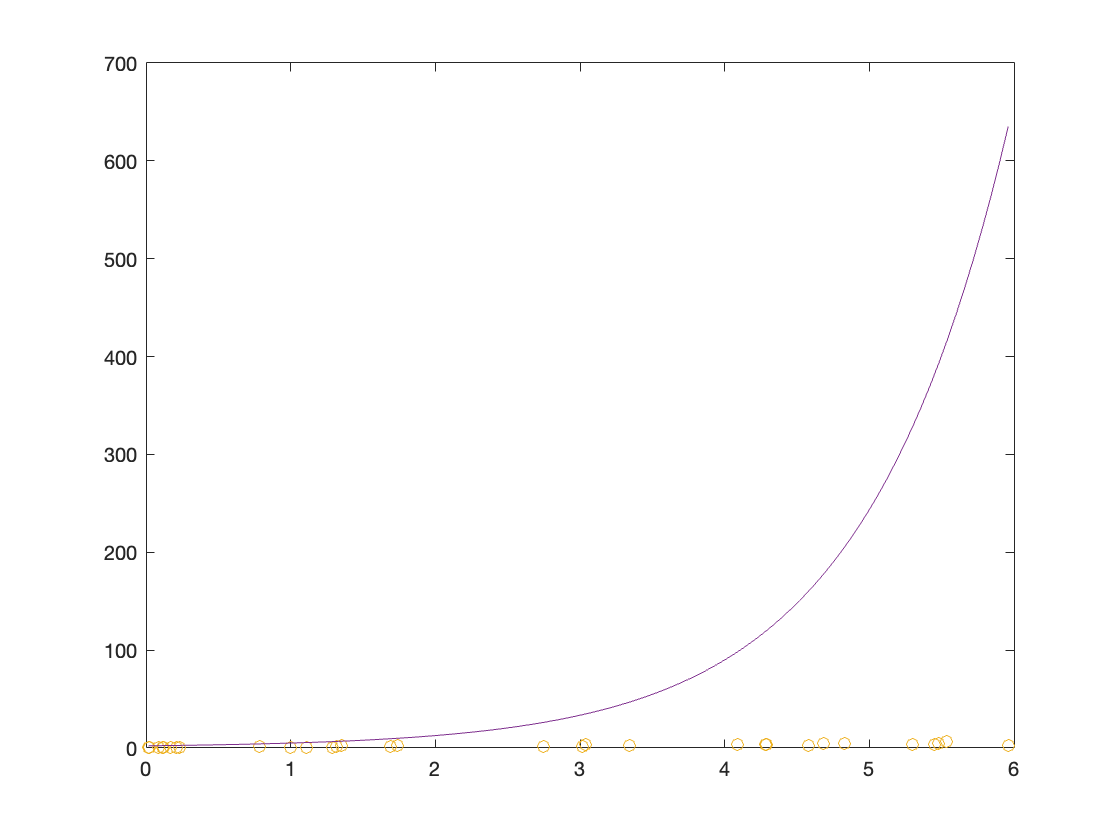

% The weight of larvae in grams
W = [0.017, 0.025, 0.02, 0.02, 0.025, 0.087, 0.111, 0.085, 0.119, 0.233, 0.0174, 0.211, 0.171, 0.21, 0.783, 1.11, 0.999, 1.29, 1.32, 1.35, 1.74, 3.02, 3.04, 3.34, 1.69, 4.09, 4.28, 4.29, 5.48, 2.75, 5.45, 4.58, 5.30, 4.83, 5.96, 4.68, 5.53];
% Oxygen consumption in millimiters/hours
R = [0.154, 0.23, 0.181, 0.18, 0.234, 0.296, 0.357, 0.26, 0.299, 0.537, 0.363, 0.366, 0.334, 0.428, 1.47, 0.531, 0.771, 0.87, 1.15, 2.48, 2.23, 2.01, 3.59, 2.83, 1.44, 3.58, 3.28, 3.40, 4.15, 1.84, 3.52, 2.96, 3.88, 4.66, 2.4, 5.1, 6.94]; 

plot(W, R, 'o')
hold on

a = myls(log(R), log(W), 2);
%P_m = @(x) exp(a(1)) + a(2) * log(x+1);
P_m = @(x) exp(a(1)) + a(2) * exp(x);

x = linspace(min(W), max(W));
%y = exp(a(1)) * P_m(x).^a(2);

plot(x,P_m(x))
hold off

E = sum((R - a(1)*W.^a(2)).^2)

E = 1.5809e+03

#### Esercizio 7)

Esaminare il Case Study riportato nel Cap. 15 del testo Applied Numerical Methods with Matlab di S.C. Chapra e ripetere l’esperimento.

**Background. **As mentioned at the end of Section 15.2, although there are many cases where a variable is linearly related to two or more other variables, multiple linear regres- sion has additional utility in the derivation of multivariable power equations of the general form:

- 
$$y = a_0 x_1^{a_1} x_2^{a_2} ... x_m^{a_m}$$


- 
$$log(y) = log(a_0) + a_1 \; log(x_1) + a_2 \; log(x_2) +... + a_m \; log(a_m)$$


A simple example relates to gas transfer in natural waters such as rivers, lakes, and estuaries. 

In particular, it has been found that the mass-transfer coefficient of dissolved oxygen $K_L$ (m/d) is related to a river’s mean water velocity $U$ (m/s) and depth $H$ (m) by

- 
$$K_L = a_0 U^{a_1} H^{a_2}$$


- 
$$log(K_L) = log(a_0) + a_1 \; log(U) + a_2 ; log(H)$$


The following data were collected in a laboratory flume at a constant temperature of 20° C:

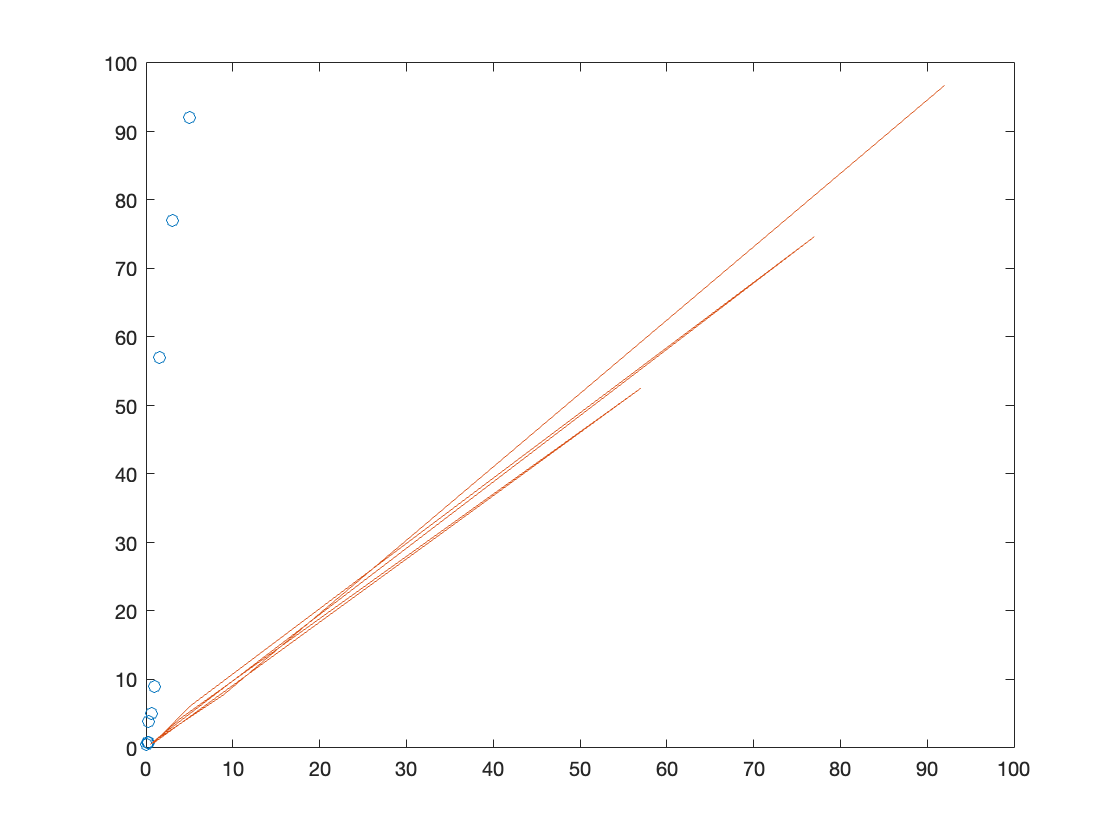

U = [0.5, 2, 10, 0.5, 2, 10, 0.5, 2, 10]; % Velocity
H = [0.15, 0.15, 0.15, 0.3, 0.3, 0.3, 0.5, 0.5, 0.5]; % Depth
K = [0.48, 3.9, 57, 0.85, 5, 77, 0.8, 9, 92]; % Dissolved oxygen

plot(U.*H, K, 'o')
hold on

u = log10(U);
h = log10(H);
k = log10(K);

B = [ones(size(k))', u', h'];
a = ((B'*B)\(B'*k'))';
% The best fit model is 
% log(K) = 0.5763 + 1.567 * log(U) + 0.507 * log(H)
% K = 3.769 U^(1.567) * H^(0.507)

y = @(x) 10^a(1) .* (x./H).^a(2) .* (x./U).^a(3);

plot(K, y(U.*H))
hold off

#### Soluzione

# Function

function coeff = myls(xdata, ydata, m)
    % xdata : vettore riga : sono le ascisse dei punti dati
    % ydata : vettore riga : sono le ordinate dei punti dati
    % m : intero : è il numero di coefficienti del polinomio
    % Questa funzione restituisce in ordine i coefficienti a_0, ..., a_m;
    % Non c'è alcun controllo sull'input;
    % Si basa sul metodo dei minimi quadrati;
    
    if length(xdata) ~= length(ydata)
        disp('La dimensione dei dati deve essere uguale!')
        return
    end
    
    m = m-1;
    n = length(xdata) - 1;
    B = ones(n+1, m+1);
    b = zeros(n+1, 1);
    A = zeros(m+1, m+1);
    
    for i=2 : m+1
        B(:, i) = (xdata').^(i-1);
    end

    A = B'* B;
    b = B' * ydata';
    coeff = (A\b)';
end